clear
clc
% system("g++ main.cpp -o main.exe -O2");
% system("main.exe --elemType hex8 --remesh --stress");
% system("main.exe --elemType hex8 --remesh");
% system("main.exe --elemType hex8 --stress");
% system("main.exe --elemType hex8");

nodeCoords = readmatrix("nodeCoords.txt");
hexaCon = readmatrix("hexaCon.txt","NumHeaderLines",0);

if isnan(hexaCon(1,3))
    hexaCon = hexaCon(2:end,:);
else
    nElems = hexaCon(1,1);
    nx = hexaCon(1,3);
    ny = hexaCon(1,4);
    nz = hexaCon(1,5);
    hexaCon = hexaCon(2:end,:);
end

plot_stress = false;

% k = readmatrix("hex8.csv");
% k = k(1:end,2:end)
% 
% k_ff = readmatrix("k_ff.txt");
% k_ff_ = [k_ff(:,2),k_ff(:,1),k_ff(:,3)];
% k_ff_ = k_ff_(k_ff(:,2)~=k_ff(:,1),:);
% k = spconvert([k_ff;k_ff_]);
% b = readmatrix("b.txt");
% % k = sparse(kff(:,1)+1,kff(:,2)+1,kff(:,3));
% % spparms('spumoni',2)
% u_ff = mldivide(k,b);
% spy(k)
% % det(k)
% % condest(k)

dof = readmatrix("dof_vector.txt");
nDOFs = max(dof(:,2)) + 3;
freeDOFs = dof(1,2);
fixedDOFs = nDOFs - freeDOFs;
dof = dof(2:end,2) + 1;

u_ff = readmatrix("u_free.txt")';
u_fs = readmatrix("u_fixed.txt")';

t_range = u_ff(1,:);
t = 3;

u_ff = u_ff(2:end,t);
u_fs = u_fs(2:end,t);
u = [u_ff;u_fs];

for i = 1:length(nodeCoords)
    ux(i) = u(dof(i)); %#ok
    uy(i) = u(dof(i)+1); %#ok
    uz(i) = u(dof(i)+2); %#ok
end

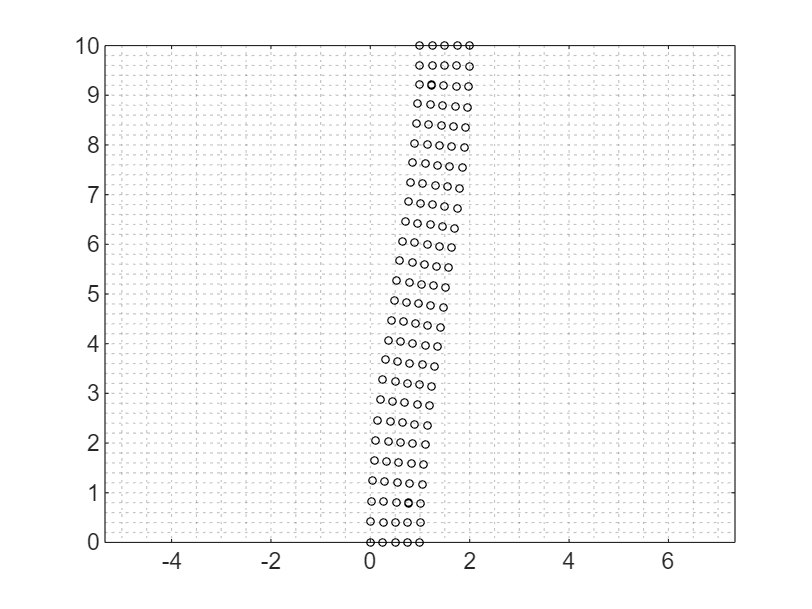

figure()
for j = 1:size(hexaCon,1)
    for i = 1:size(hexaCon,2)
        x(i,1) = nodeCoords(hexaCon(j,i),2) + ux(hexaCon(j,i)); %#ok
        y(i,1) = nodeCoords(hexaCon(j,i),3) + uy(hexaCon(j,i)); %#ok
        z(i,1) = nodeCoords(hexaCon(j,i),4) + uz(hexaCon(j,i)); %#ok
        pGroup(i,1) = nodeCoords(hexaCon(j,i),5); %#ok
    end
    hold on
    % Volume Shading
    % trisurf(convhull(x,y,z), ...
    %     x, y, z, ...
    %     'FaceAlpha',0.2, ...
    %     'EdgeColor','None');

    % Nodes
    scatter3(x,y,z,10,'k')
    hold off

    % Element Numbering
    % text(mean(x),mean(y),mean(z), ...
    %     string(j),'Interpreter','latex', ...
    %     'Color','r')
end

% Node Numbering
% for i = 1:length(nodeCoords)
%     text(nodeCoords(i,2) + ux(i), ...
%         nodeCoords(i,3) + uy(i), ...
%         nodeCoords(i,4) + uz(i), ...
%         string(nodeCoords(i,1)), ...
%         'Interpreter','latex', ...
%         "VerticalAlignment","bottom")
%
%     if (nodeCoords(i,5) ~= 0)
%         hold on
%         scatter3(nodeCoords(i,2) + ux(i), ...
%             nodeCoords(i,3) + uy(i), ...
%             nodeCoords(i,4) + uz(i),20,'r')
%         hold off
%     end
% end

% view([60,30])
view([0,90])
axis equal
grid minor
box on


% xlim([0,1])
% ylim([0,10])

if (plot_stress)
    range_xyz = [min(nodeCoords(:,2:4))',...
        max(nodeCoords(:,2:4))']; %#ok
    % range_u = [[min(ux),max(ux)];
    %     [min(uy),max(uy)];
    %     [min(uz),max(uz)]];
    % range_xyz = range_xyz + range_u;
    dxdydz = diff(range_xyz,1,2)./[nx;ny;nz];
    dist_elem = sqrt(sum(dxdydz.^2));

    sigma = readmatrix("stress.txt")/1e9;

    range_n = [min(sigma(:,1:3),[],"all")',
        max(sigma(:,1:3),[],"all")'];
    range_t = [min(sigma(:,4:6))',max(sigma(:,4:6))'];
    cl_map = colormap("jet");

    figure("Position",[0,0,300,300])
    tiledlayout(1,3,"Padding","tight", ...
        "TileSpacing","tight");
    for tile = 1:3
        nexttile(tile);
        for j = 1:size(hexaCon,1)
            for i = 1:size(hexaCon,2)
                x(i,1) = nodeCoords(hexaCon(j,i),2);
                y(i,1) = nodeCoords(hexaCon(j,i),3);
                z(i,1) = nodeCoords(hexaCon(j,i),4);
            end
            box on
            hold on
            ind = round((range_n(2) - ...
                sigma(j,tile))/diff(range_n) * ...
                (length(cl_map)-1)) + 1;
            colour = cl_map(ind,:);
            scatter3(mean(x),mean(y),mean(z), ...
                dist_elem * 100,colour,'filled')
        end
        hold off
    end
    cb = colorbar("Ticks",[0,1], ...
        "TickLabels",string(range_n));
    colormap("jet")
    cb.Layout.Tile = "south";
    cb.Ruler.TickLabelRotation = 90;

    figure("Position",[0,0,300,300])
    tiledlayout(1,3,"Padding","tight", ...
        "TileSpacing","tight");
    for tile = 1:3
        nexttile(tile);
        for j = 1:size(hexaCon,1)
            for i = 1:size(hexaCon,2)
                x(i,1) = nodeCoords(hexaCon(j,i),2);
                y(i,1) = nodeCoords(hexaCon(j,i),3);
                z(i,1) = nodeCoords(hexaCon(j,i),4);
            end
            box on
            hold on
            ind = round((range_t(tile,2) - ...
                sigma(j,tile + 3))/diff(range_t(tile,:)) * ...
                (length(cl_map)-1)) + 1;
            colour = cl_map(ind,:);
            scatter3(mean(x),mean(y),mean(z), ...
                dist_elem * 100,colour,'filled')
        end
        hold off
        cb = colorbar("Ticks",[0,1], ...
            "TickLabels",string(range_t(tile,:)));
        colormap("jet")
        cb.Layout.Tile = "south";
        cb.Ruler.TickLabelRotation = 90;
    end
end